# Examen TDI Enero 2017

#### Teoría

**1.- Se desea analizar el efecto de restauración del Wiener sobre una imagen que ha sido degradada mediante una función lineal de degradación. Para dicho análisis se dispone de la DFT de la imagen original F(u,v), como de la DFT de la imagen degradada G(u,v). Por simplicidad se considerarán las imágenes siguientes**

F(u,v) =  [39 184 39; 78 892 78; 39 184 39]

G(u,v) = [13 92 13; 39 446 39; 13 92 13]

Además de degradación lineal se ha introducido ruido aditivo. La imagen degradada G(u,v) con ruido es ahora

G(u,v) = [30 92 15; 39 446 49; 15 92 30]

Calcular la función de transferencia del filtro de Wiener que restaure la imagen

Inicializamos F(u,v)

F = [39 184 39; 78 892 78; 39 184 39];

Primero calcularemos el ruido de la G(u,v) al final menos al principio

G = [13 92 13; 39 446 39; 13 92 13];
G_Fin = [30 92 15; 39 446 39; 15 92 30];

Obtenemos el ruido

N = G_Fin - G;

Calculamos el cuadrado

N_Cuad = N.^2;

El filtro Wiener

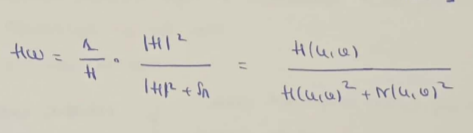

También tenemos que

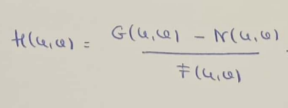

Calculamos H

Obtenemos el denominador

H_Denominador = G - N;

Y lo dividimos entre F

H = H_Denominador./F;

Lo elevamos al cuadrado

H_Cuad = H.^2;

Hacemos los últimos cálculos, en el numerador debemos sumar H_Cuad y N_Cuad

H_Num = H_Cuad + N_Cuad;

Hacemos el calculo final

Hw = H ./ H_Num;

**2.- La técnica Deep Learing está revolucionando el análisis automático de imágenes**

a) Describir las diferencias entre una red neuronal convencional y Deep Learning

Una red neuronal convencional emula el funcionamiento de nuestro cerebro, a partir d e otorgar pesos sinápticos a los distintos datos, almacenan el conocimiento distribuido. Se basan en una serie de datos, almacenan el conocimiento distribuido. Se basa en una serie de 'neuronas' artificiales unidad entre si que permiten generar un proceso

EN cuanto al Deep Learning se encuentra inspirado en el funcionamiento del cerebro, pero dista de ser igual, tiene múltiples capas de proceso, puede aprender tanto de manera supervisada como no supervisada y su jerarquía se basa en capas *bottom-up*, lo que indica que cada pequeña parte se realiza con detalle para poder generar sistemas cada vez más grandes

b) Describir lo más detallado posible el funcionamiento de una red neuronal convolucional

A partir de una imagen, de la cual toammos sus píxeles como valor de entrada, todos ellos normalizados (pix/255). A continuación de la imagen tomamos grupos de píxeles del tamaño de la matriz Kermel, cada Kermel representará los pesos del campo receptivo local, lo que es equivalente a un filtro adaptativo al hacer un conjunto de Kernels, submuestrearemos la imagen (pooling), esto implica reducir la cantidad de neuronas antes de seguir convolucionando para ir reduciendo el tamaño de las siguientes capas (por lo que tendremos un procesamiento más óptimo), así en cada convolución, a más convoluciones hagamos, la red podrá reconocer cada vez formas más complejas

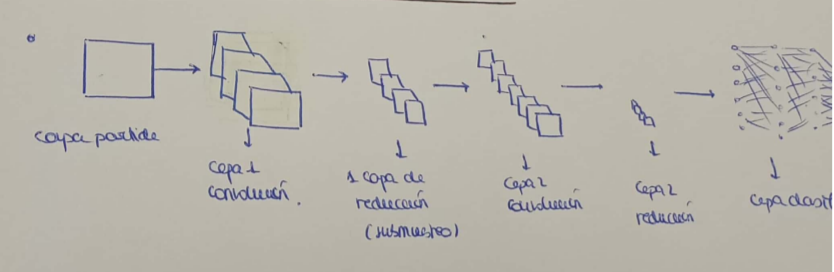

#### Problemas

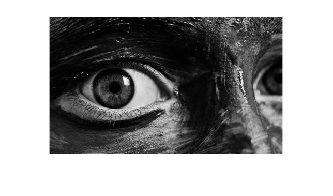

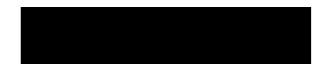

x = 109;
Y = Problema_1('Monocroma.jpg', x);

**1.- Programar una función que maximice el contraste de una imagen monocroma de entrada, considerando que el valor de gris 100 debe permanecer inalterado**

**Imagen será la imagen que introduzcamos**

**x será el contraste que queramos introducir**

**Para aplicar el contraste necesitaremos de la fórmula s = cr + b**

function Y = Problema_1(Imagen, x)

Leemos la imagen de entrada

Imagen = imread(Imagen);
imshow(Imagen)

Obtenemos el tamaño de la imagen

[N, M] = size(Imagen);

Inicializamos la salida Y

Y = zeros(N, M);

Calculamos el contraste a partir de un doble bucle para pasar por todos los píxeles de la imagen

La ecuación que observamos en s la obtenemos despejando el siguiente sistema

Podemos observar que si despejamos

c = (100/(100-x))

b = -((100*x)/(100-x))

for i = 1:N
    for j = 1:M
        r = Imagen(i,j);
        s = (100/(100-x))*r --((100*x)/(100-x));
        Y(i,j) = s;
    end
end
figure
imshow(Y)
end

**2.- Deseamos que el personaje del programa SCRATCH haga el siguiente movimiento utilizando matrices de transformación homogeneas**

** 1º La figura parte con la esquina inferior izquierda en el centro de la imagen**

**2º Se mueve hasta la esquina superior derecha de la imagen**

**3º Justo cuando algún punto de la figura se salga de la imagen se debe dar la vuelta a la figura**

**4º Entonces se mueve recorrido el mismo camino en sentido inverso hasta alcanzar el centro de la imagen de nuevo**

**Programar la función completa y guardar el resultado en un vídeo**

- F, es el Fondo

- E, es la imagen de entrada

- Xo e Yo son las posiciones iniciales en las que se encuentra la imagen

- alfa es los grados que queremos rotar la imagen

- Sx y Sy es cuanto queremos que se agrande la imagen

function Transformada(F, E, Xo, Yo, alfa, Sx, Sy)

Igualamos la salida al fondo de la imagen

R = F;

Obtenemos el tamaño de las imagenes

[A, B] = size(E);
[C, D] = size(F);

La Matriz de translación

Tt = [1, 0, Xo; 0, 1, Yo; 0, 0, 1];

La Matriz de rotación

Tr = [cos(alfa), sin(alfa), 0; -sin(alfa), cos(alfa), 0; 0, 0, 1];

La Matriz del escalado

Ts = [Sx, 0, 0; 0, Sy, 0; 0, 0, 1];

Matriz para centrar el eje de rotación

Ttr = [1 0 -round(A/2); 0 1 -round(B/2); 0 0 1];

Recorreemos la imagen con 2 bucles for

for i = 1:A
    for j=1:B

El orden es, de derecha a izquierda

Escala

Traslación

Rotación

Traslación

        T = Tt*Tr*Ttr*Ts;
        V = T*[i;j;1];
        u = round(V(1));
        v = round(V(2));

Comprobamos los bordes del la imgen respecto al fondo

        if u <= C && v <= D && u > 0 && v> 0
            R(u,v) = E(i,j);
        end
    end

end
end

**3.- Se desea transmitir video en tiempo real a través de una conexión radio (5 Mbits/seg). Las imágenes son en color RGB de tamaño 160x120 y se desea que la aplicación funcione a 20 imagenes por segundo. Programe una función que permita transmitir el video en tiempo real con la mayor calidad posible**